## Задание 1

function plotPoleZeroMaps(sys, name)
    % plotPoleZeroMaps - строит карты нулей и полюсов для разомкнутой и замкнутой систем
    %
    % Вход:
    %   sys - передаточная функция разомкнутой системы (объект tf)
    %
    % Выход:
    %   Графики нулей и полюсов для разомкнутой и замкнутой систем

    % Проверка, что входная система является объектом tf
    if ~isa(sys, 'tf')
        error('Входная система должна быть объектом tf.');
    end

    % Построение карты нулей и полюсов для разомкнутой системы
    figure('Position', [0 0 800 500]);

    subplot(1, 2, 1); % Разделение фигуры на два графика
    pzmap(sys);
    % grid on;
    title('Нули и полюса разомкнутой системы');
    xlabel('Re');
    ylabel('Im');
    
    % Создание замкнутой системы с обратной связью
    sys_closed = feedback(sys, 1);

    % Построение карты нулей и полюсов для замкнутой системы
    subplot(1, 2, 2);
    pzmap(sys_closed);
    % grid on;
    title('Нули и полюса замкнутой системы');
    xlabel('Re');
    ylabel('Im');

    exportgraphics(gcf, 'figs/' + name + '.png', 'Resolution', 300);
end

function plotStepResponses(sys, name)
    % plotStepResponses - выполняет моделирование и строит переходные характеристики
    %                     для разомкнутой и замкнутой систем.
    %
    % Вход:
    %   sys - передаточная функция разомкнутой системы (объект tf)
    %
    % Выход:
    %   График переходных характеристик для разомкнутой и замкнутой систем.

    if ~isa(sys, 'tf')
        error('Входная система должна быть объектом tf.');
    end

    % Создаем фигуру для отображения
    figure('Position', [100, 100, 1200, 500]); % Широкая фигура для сравнения

    % Переходная характеристика разомкнутой системы
    subplot(1, 2, 1);
    [y_open, t_open] = step(sys);
    plot(t_open, y_open, 'b', 'LineWidth', 2);
    grid on;
    xlabel('Time (s)');
    ylabel('Amplitude');
    title({"Переходная характеристика", "разомкнутой системы"});

    % Переходная характеристика замкнутой системы
    sys_closed = feedback(sys, 1);
    subplot(1, 2, 2);
    [y_closed, t_closed] = step(sys_closed);
    plot(t_closed, y_closed, 'r', 'LineWidth', 2);
    grid on;
    xlabel('Time (s)');
    ylabel('Amplitude');
    title({"Переходная характеристика", "замкнутой системы"});

    exportgraphics(gcf, 'figs/' + name + '.png', 'Resolution', 300);
end


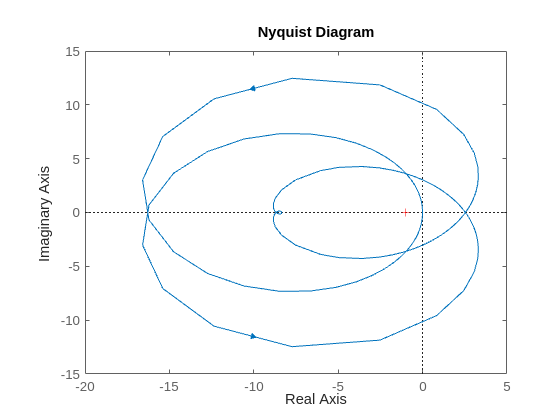

num = [100, 100, 100, 100, -100];
den = [1, -6, 11, -4, -10, 12];
open_sys_1 = tf(num, den);
close_sys_1 = feedback(open_sys, 1);
figure;
nyquist(open_sys_1);

pole(open_sys_1)

ans =    3.0000 + 0.0000i
  -1.0000 + 0.0000i
   2.0000 + 0.0000i
   1.0000 + 1.0000i
   1.0000 - 1.0000i


pole(close_sys_1)

ans =  -92.8151 + 0.0000i
  -1.3498 + 0.0000i
  -0.1663 + 1.1765i
  -0.1663 - 1.1765i
   0.4975 + 0.0000i


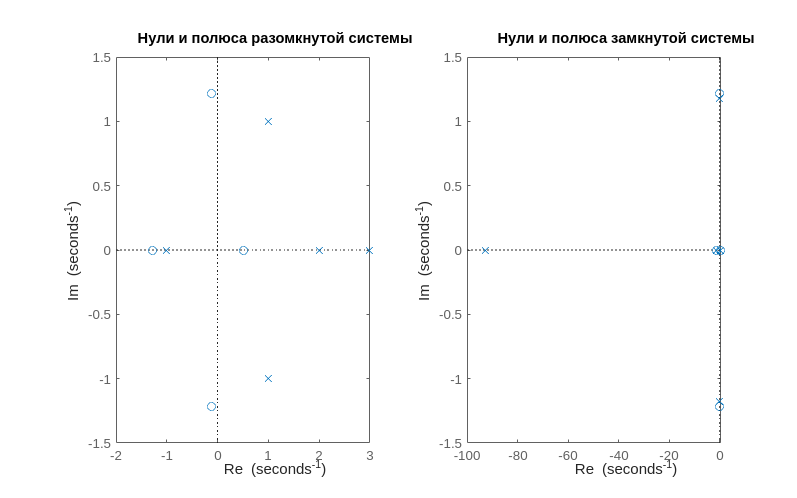

plotPoleZeroMaps(open_sys_1, "task_1_obj_1_zeros_poles");

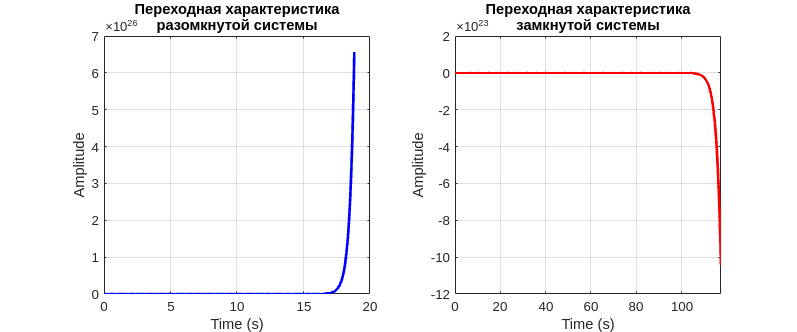

plotStepResponses(open_sys_1, "task_1_obj_1_step");

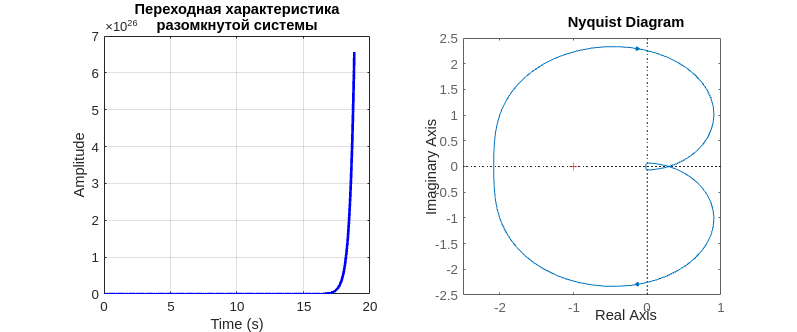

num = [-100];
den = [1, 11, 46, 194, 100, 48];
open_sys_2 = tf(num, den);
close_sys_2 = feedback(open_sys_2, 1);
figure;
nyquist(open_sys_2);

pole(open_sys_2)

ans =   -8.1009 + 0.0000i
  -1.1890 + 4.4248i
  -1.1890 - 4.4248i
  -0.2606 + 0.4630i
  -0.2606 - 0.4630i


pole(close_sys_2)

ans =   -8.0765 + 0.0000i
  -1.1348 + 4.4632i
  -1.1348 - 4.4632i
  -0.9676 + 0.0000i
   0.3137 + 0.0000i


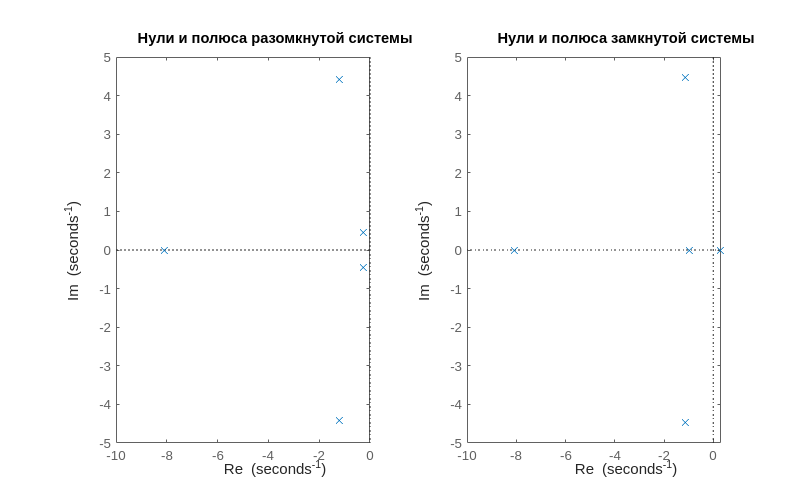

plotPoleZeroMaps(open_sys_2, "task_1_obj_2_zeros_poles");

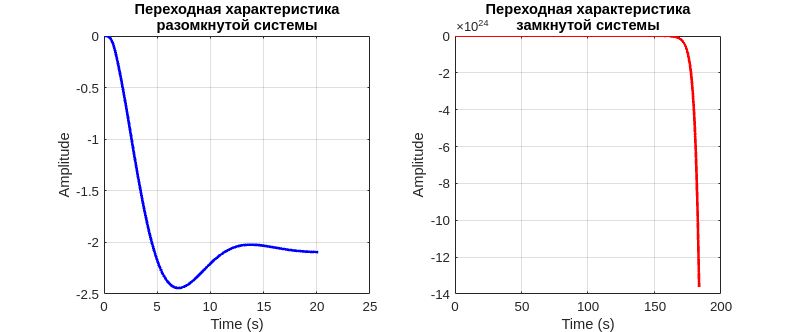

plotStepResponses(open_sys_2, "task_1_obj_2_step");

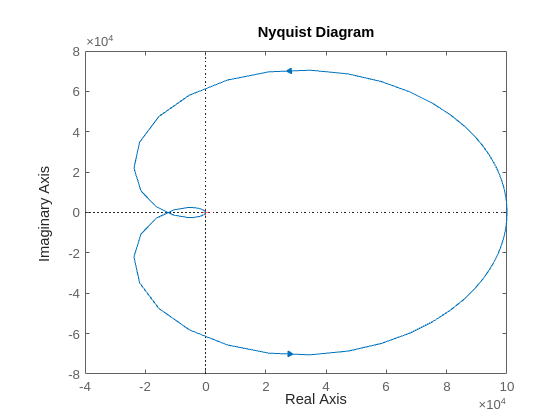

num = [100000, 100, -1000, -10000, -1000, -100];
den = [1, -6, 11, -4, -10, 12];
open_sys_3 = tf(num, den);
close_sys_3 = feedback(open_sys_3, 1);
figure;
nyquist(open_sys_3);

pole(open_sys_3)

ans =    3.0000 + 0.0000i
  -1.0000 + 0.0000i
   2.0000 + 0.0000i
   1.0000 + 1.0000i
   1.0000 - 1.0000i


pole(close_sys_3)

ans =    0.5043 + 0.0000i
  -0.2016 + 0.3927i
  -0.2016 - 0.3927i
  -0.0510 + 0.0797i
  -0.0510 - 0.0797i


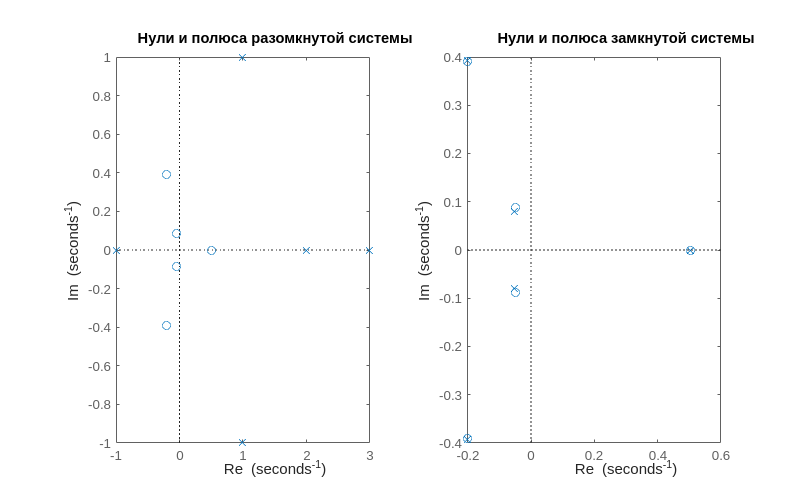

plotPoleZeroMaps(open_sys_3, "task_1_obj_3_zeros_poles");

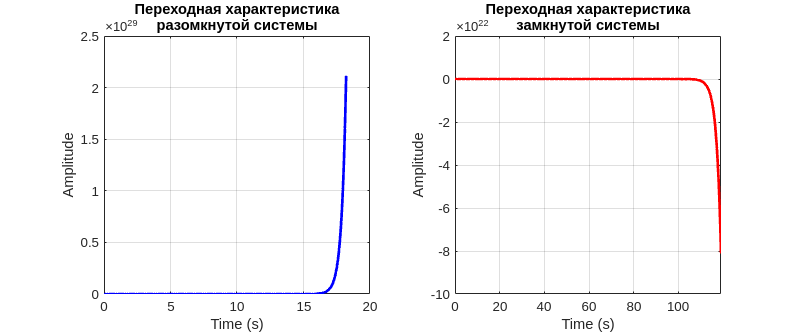

plotStepResponses(open_sys_3, "task_1_obj_3_step");

% Первая система: 4 неустойчивых полюса (разомкнутая), 1 у замкнутой
p1_open = [2, 3, -1, -2+1i, -2-1i]; % Полюса разомкнутой
z1_open = [-3, -4];                % Нули разомкнутой
W1 = zpk(z1_open, p1_open, 1);     % Передаточная функция

% Вторая система: 0 неустойчивых полюсов (разомкнутая), 1 у замкнутой
p2_open = [-2, -3, -4, -1+2i, -1-2i];
z2_open = [-1, -2];
W2 = zpk(z2_open, p2_open, 1);

% Третья система: 4 неустойчивых полюса (разомкнутая), 0 у замкнутой
p3_open = [3, 4, -1, -2+1i, -2-1i];
z3_open = [-3, -4];
W3 = zpk(z3_open, p3_open, 1);

systems = {W1, W2, W3};
titles = {'System 1', 'System 2', 'System 3'};

% Анализ каждой системы
for i = 1:3
    W_open = systems{i};
    
    % Карты нулей и полюсов
    figure;
    pzmap(W_open);
    title(['Poles and Zeros (Open Loop) - ', titles{i}]);
    grid on;
    saveas(gcf, ['figs/pz_open_', titles{i}, '.png']);
    
    % Замкнутая система
    W_closed = feedback(W_open, 1);
    figure;
    pzmap(W_closed);
    title(['Poles and Zeros (Closed Loop) - ', titles{i}]);
    grid on;
    saveas(gcf, ['figs/pz_closed_', titles{i}, '.png']);
    
    % Переходная характеристика
    figure;
    subplot(2, 1, 1);
    step(W_open);
    title(['Step Response (Open Loop) - ', titles{i}]);
    grid on;
    subplot(2, 1, 2);
    step(W_closed);
    title(['Step Response (Closed Loop) - ', titles{i}]);
    grid on;
    saveas(gcf, ['figs/step_', titles{i}, '.png']);
    
    % Годограф Найквиста
    figure;
    nyquist(W_open);
    title(['Nyquist Plot - ', titles{i}]);
    grid on;
    saveas(gcf, ['figs/nyquist_', titles{i}, '.png']);
    
    % ЛАФЧХ
    figure;
    bode(W_open);
    title(['Bode Plot - ', titles{i}]);
    grid on;
    saveas(gcf, ['figs/bode_', titles{i}, '.png']);
end
